Test the behavior of the Demand mode model. 

Desired behavior: Percent of Carbon consumed that goes towards enzyme production decreases linearly as a function of the carbon uptake rate, approaching 0 as glc influx approaches its max value * alpha

%%SCRIPT CONTROL VARIABLES
refreshmodel = true;
runalphamodels = true;

v.richmedia = true;

%%STRATEGY VARIABLES
v.defaultbound = 10; %default exchange upper bound
%v.maxEnzymeRate = 1; %maximum enzyme:biomass ratio by weight for fixed production. 1:1 w/ alpha=1 should mean half of all amino acids go into enzyme
v.alpha = 0.1; %fixed percentage of the maximum enzyme rate being expressed

%%ENZYME VARIABLES. See https://www.brenda-enzymes.org/enzyme.php?ecno=3.2.1.4
%values used: wild-type T.ressei on 4-methylumbelliferyl cellobioside. https://www.brenda-enzymes.org/literature.php?e=3.2.1.4&r=737187
v.kcat_cel = 0.01; %mmol converted / mmol enzyme / second  %TODO: Confirm units
v.km_cel = 0.125; %Units = mmoles/cm^3

%%Glucose variables
v.km_glc = 0.01; %millimoles/cm^3.
v.vmax_glc = 10;
v.glcpercellulose = 218.2;%how many units of glucose get released per unit cellulose? 1:1 assumes units are by weight
    %Avicel degree of polymerization cite : https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3217711/
%v.biomassperglc = 1/(1.447e9); %how many units of biomass are produced for every unit glc consumed?
    %weight of E coli / weight of glc molecule = 433fg / (2.992e-22g) = 4.33e-13 / (2.992e-22) = 1.447e9
v.glcuptakerate = -v.vmax_glc; %bound for the GLC import reaction
                         %This should be higher than required for max enzyme production

%%DECAY/DEATH VARIABLES
v.enzdecayperhour = 0;
v.deathrate = 0; %per timestep
                         
%Enzyme variables v 2- set high to check that everything works OK
%v.kat = 100;
%v.km = 0.0001;

%%WORLD/LAYOUT VARIABLES
%v.dilutionrate = 1/24; %fraction of media replaced per hour
%v.dilutionrate = 1/12; %fraction of media replaced per hour
v.xdim = 1;
v.ydim = 1;
v.diff_cel = 0; %Diffusion constants
v.diff_enz = 1e-6; %Default is 1e-6;
v.diff_glc = 1e-6;
%v.enzymeperglc = 0.05; %how many units of enzyme are produced for every unit glc consumed?
v.initcellulose = 1;
v.initglc = 1e-3; %needed to bootstrap production
v.initmedia = 1; %amount of all other media added
v.initialpop = 1e-3;
v.initO2 = 1000; %oxygen level in the media
v.initNH4 = 1000; %ammonium level in the media
v.initPi = 1000;
v.initK = 1000;
v.initSO4 = 1000;

%%COMETS EXECUTION VARIABLES
v.maxcycles = 100;
v.timestep = 1; %1/(60*60); %1/3600 hours = 1 second. 
v.filepath = 'C:\sync\biomes\cellulose\optima\temp';
v.writemedialog = true;
v.writebiomasslog = true;
v.writefluxlog = false;
v.lograte = 1;
v.maxspacebiomass = 1000;
v.spaceWidth = 10^(1/3);
v.lograte = 1;

v_default = v;

%%DEFAULT MODEL
if refreshmodel
    %model_default = load('C:\sync\biomes\models\ecoli_core_model_norm.mat'); %model with metabolite names normalized
    model_default = load('C:\sync\biomes\models\iJO1366 (1).mat'); %model with metabolite names normalized
    model_default = model_default.iJO1366;
end

%alphas = [.5 .2 .8];
alphas = 3

alphas = 3

models = {};
for i = 1:length(alphas)
    a = alphas(i);
    v.alpha = a;
    models{i} = buildEcoliModel(v,model_default,['Demand(' num2str(a) ')'],'demand');
    
end

if runalphamodels
    newmodels = cell(length(models),1);
    for i = 1:length(models)
        newmodels{i} = runModel(models{i});
    end
    models = newmodels;
end


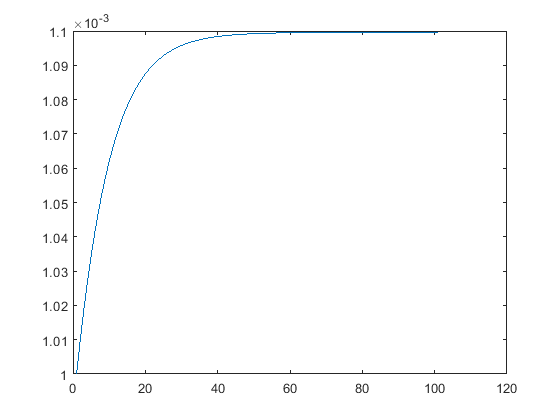

m = models{end};
media = parseMediaLog([m.v.filepath '/log_media.m']);
biomass = parseBiomassLog([m.v.filepath '/log_biomass.m']);
plot(biomass.biomass);

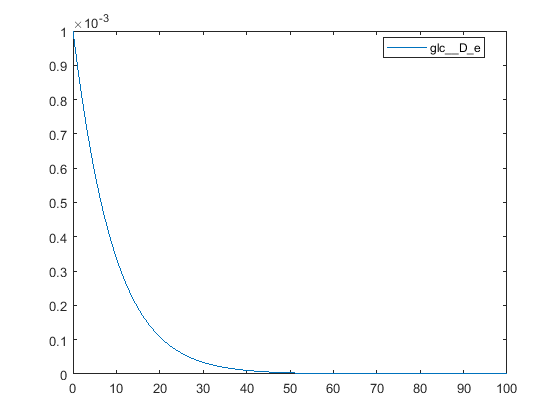

plotMediaTimecourse(media,{'glc__D_e'});

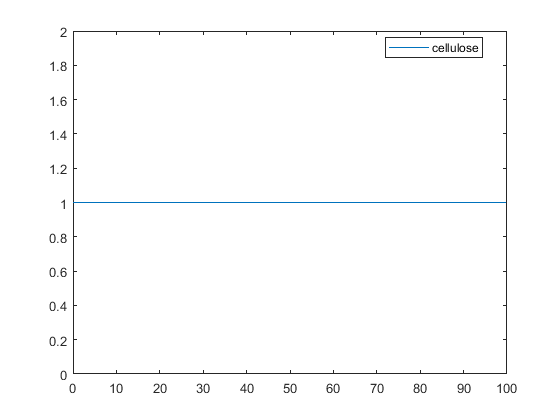

plotMediaTimecourse(media,{'cellulose'});

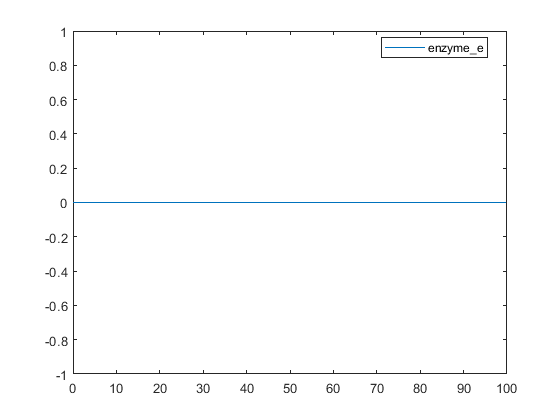

plotMediaTimecourse(media,{'enzyme_e'});

function model = runModel(model)

layout = buildCelOptLayout(model);
%layout = setMedia(layout,'o2_e',model.v.initO2);
%layout = setMedia(layout,'nh4_e',model.v.initNH4);
if model.v.richmedia
%    layout.media_amt(layout.media_amt==0) = 10;
    layout.media_amt(layout.media_amt==0) = .0001;
    layout.media_amt(stridx('enzyme_e',layout.mets)) = 0;
end

createCometsFiles(layout,model.v.filepath,'layout_temp.txt');
runCometsOnDirectory(model.v.filepath);

tab = parseBiomassLog([model.v.filepath '\log_biomass.m']);
model.biomass = tab.biomass; %no need to sum if there's no biomass diffusion
model.timestep = tab.t;

if model.v.writemedialog
    media = parseMediaLog([model.v.filepath '\log_media.m'],{'enzyme_e', 'cellulose', 'glc__D_e', 'ac_e'});
    model.enzyme_amt = zeros(length(model.timestep),1);
    model.cellulose_amt = zeros(length(model.timestep),1);
    model.glc_amt = zeros(length(model.timestep),1);
    model.acetate_amt = zeros(length(model.timestep),1);
    for i = 1:length(model.timestep)
        time = model.timestep(i);
        enzrows = (media.t == time) & strcmp(media.metname,'enzyme_e');
        celrows = (media.t == time) & strcmp(media.metname,'cellulose');
        glcrows = (media.t == time) & strcmp(media.metname,'glc__D_e');
        acrows = (media.t == time) & strcmp(media.metname,'ac_e');
        subtab = media(enzrows,:);
        model.enzyme_amt(i) = sum(subtab.amt);
        subtab = media(celrows,:);
        model.cellulose_amt(i) = sum(subtab.amt);
        subtab = media(glcrows,:);
        model.glc_amt(i) = sum(subtab.amt);
        subtab = media(acrows,:);
        model.acetate_amt(i) = sum(subtab.amt);
    end
end

end